# QLAN Optimization Test File

## Parameters

[user_names, eff_N, d_N] = loadUsersFromFile('optica_users.txt');

N = numel(eff_N); % Max number of users
K = 12; % Number of frequency channel pairs
D = 4; % quantum state dimensionality; dimension of two-qubit system
coinc_wind_s = 1.024e-9; % detector coincidence window in seconds
h = 6.626e-34;

% list of node pairs constituting network links
links = nchoosek(1:N, 2); % fully connected links
disp(links)

     1     2
     1     3
     1     4
     2     3
     2     4
     3     4



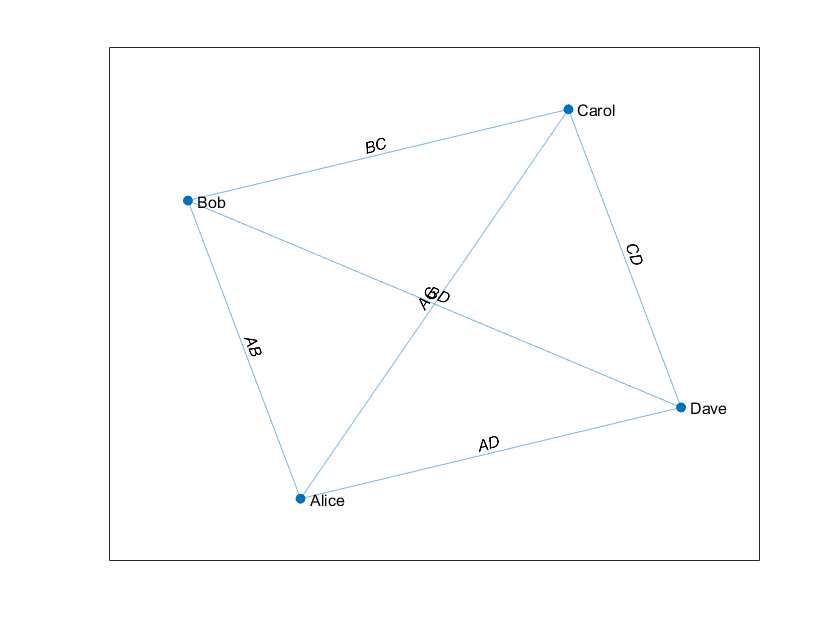

L = size(links,1); % Number of links in specified network

% Constructing edge table with edge labels
strfun = @(stem) sprintf("l%s", num2str(stem));
link_names = arrayfun(strfun, (1:L)', 'UniformOutput', 1);
link_names = {'AB', 'AC','AD','BC','BD','CD'}';
EdgeTable = table(links, link_names, 'VariableNames', {'EndNodes', 'EdgeNames'});

% Construct table of node labels
strfun = @(stem) sprintf("n%s", num2str(stem));
% user_names = arrayfun(strfun, (1:N)', 'UniformOutput', 1);
NodeTable = table(user_names, 'VariableNames', {'Name'});

% construct graph object using edge table and node names
g = graph(EdgeTable, NodeTable);

% Plot graph with names
fig = plot(g);
fig.EdgeLabel = g.Edges.EdgeNames;

inc_mat = abs(incidence(g));
disp(full(inc_mat))

     1     1     1     0     0     0
     1     0     0     1     1     0
     0     1     0     1     0     1
     0     0     1     0     1     1



## Channel Parameters

% Each channel has an initial state rho_k
psi_m = [0;1;-1;0]./sqrt(2); % EPR state vector |HV> - |VH>
rho_psi_m = psi_m*psi_m'; % construct density matrix for initial entangled states
rho_K = repmat(rho_psi_m, 1, 1, K); % initial channel states are all |HV>-|VH>

% Each channel has unitary describing change in quantum states after
% transmission. U_K(:,:,k) returns the unitary of the kth channel pair
U_K = repmat(eye(D),[1,1,K]); % Ideal case where channel unitaries are identities

% Define spectrum partitioning; central stop band assumed
wss_f0_hz = 192.3125e12; % WSS center frequency
chan_width_hz = 24e9;
wss_Pin_W = 6.04e-14; % laser power into WSS in watts
spect_fwhm_hz = 310e9; % power spectrum FWHM
power_spect = sqrSincPowerSpect(wss_f0_hz, spect_fwhm_hz, wss_Pin_W); % obtain function handle to gaussian power spectrum

## Calculating channel fluxes

% Each channel has associated photon flux which can be calculated from
% input power spectrum and spectrum partitioning

% Matrices of channel boundaries
lo_freq_bounds = zeros(K,2); % freq bounds of lower spectral slices
hi_freq_bounds = zeros(K,2); % freq bounds of upper spectral slices

for k = 1:K
        lo_freq_bounds(k,:) = sort([wss_f0_hz - chan_width_hz*(k+1/2), wss_f0_hz - chan_width_hz*(k-1/2)]);
        hi_freq_bounds(k,:) = sort([wss_f0_hz + chan_width_hz*(k-1/2), wss_f0_hz + chan_width_hz*(k+1/2)]);
end


chan_flux = zeros(K, 1);
for k = 1:K
    chan_flux(k) = 1/h*integral(@(x) power_spect(x)./x, lo_freq_bounds(k,1), lo_freq_bounds(k,2));
    chan_flux(k) = chan_flux(k) + ...
                   1/h*integral(@(x) power_spect(x)./x, hi_freq_bounds(k,1), hi_freq_bounds(k,2));
    chan_flux(k) = chan_flux(k)/2; % divide by two to get biphoton flux instead of single photon flux
end

## Constructing allocation matrix from allocation vector

% Random allocation vector; index with channel number to obtain assigned
% link number
alloc_vect = zeros(K,1);
for k = 1:K
    alloc_vect(k) = floor((k-1)/2)+1;
end
% alloc_vect = ones(K,1);
disp(alloc_vect)

     1
     1
     2
     2
     3
     3
     4
     4
     5
     5
     6
     6



% Sparse matrix representation of allocation vector where row indices are
% link labels and column indices are channel labels.
% E.g., if alloc_mat(3,5) == 1, then channel 5 is assigned to link 3-1=2.
% if alloc_mat(1,2) == 1, then channel 2 is assigned to link 1-1=0 (null link)
alloc_mat = double((0:L)' == alloc_vect');

% Link flux = sum(fluxes of allocated channels)
% link_fluxes = total photon fluxes corresponding to each link
link_fluxes = alloc_mat*chan_flux;

% User flux = sum(non-null link fluxes connected to user)
user_fluxes = inc_mat*link_fluxes(2:end);


## Calculating count rates

R_N = eff_N/2 .* user_fluxes + d_N; % vector of user single count rates
% R_N = [2.6e5 3.3e5 5.5e3 3.3e3]'; % Overriding RN with values from Optica paper
disp(R_N)

   1.0e+03 *

    6.6119
    4.2445
    0.0826
    0.0282




A_L = zeros(L,1); % vector of link accidental rates (excluding null)
C_L = zeros(L,1); % vector of link true coincidence rates (excluding null)
full_inc_mat = logical(full(inc_mat)); % ensure incidence matrix not in sparse form
for i = 1:L
    % for each link, calculate product of single count rates for connected
    % users and coincidence window to get accidental coincidence rate
    A_L(i) = 8*coinc_wind_s*prod(R_N(full_inc_mat(:,i)));
    
    % for each non-null link calculate product of efficiencies of connceted users
    % and link photon flux to get true coincidence rate
    C_L(i) = link_fluxes(i+1)*prod(eff_N(full_inc_mat(:,i)));
end

disp(A_L)

    0.2299
    0.0045
    0.0015
    0.0029
    0.0010
    0.0000



disp(C_L)

  451.4135
    9.0769
    3.3745
    4.2410
    1.0578
    0.0084



## Calculating Received State

% Noise-entanglement weight per link
lambda_L = 1./(1+A_L./C_L);
lambda_L_3D = reshape(lambda_L,1,1,L);

% Calculating noise state = 1-lamda*eye(D)/D for each link
noise_L = pagemtimes(1-lambda_L_3D, repmat(eye(D)./D, 1, 1, L));
% disp(noise_L)

% rho_L = density matrix shared across links
rho_L = zeros(D,D,L);
for i = 2:(L+1) % iterate over non-null links
    U = U_K(:,:,logical(alloc_mat(i,:))); % unitaries of channels allocated to link i-1
    rho = rho_K(:,:,logical(alloc_mat(i,:))); % initial states of channels allocated to link i-1
    flux = chan_flux(logical(alloc_mat(i,:))); % get channel fluxes allocated to link i-1
    flux = reshape(flux,1,1,numel(flux)); % reshape to 3D vector for quicker math
    
    % calculate sum of all flux*U*rho*U' density matrices
    rho_L(:,:,i-1) = sum(pagemtimes(flux,pagemtimes(pagemtimes(U,rho),'none',U,'ctranspose')),3);
end

% weighting entangled state using lambda and portion of total flux
link_weights = lambda_L ./ link_fluxes(2:end); % Calculate weights
link_weights_3D = reshape(link_weights, 1, 1, L); % reshape to 3D for quicker math
rho_L = pagemtimes(link_weights_3D, rho_L); % weight_l*rho_l

sigma_L = rho_L + noise_L;

disp(noise_L)


(:,:,1) =

   1.0e-03 *

    0.1273         0         0         0
         0    0.1273         0         0
         0         0    0.1273         0
         0         0         0    0.1273


(:,:,2) =

   1.0e-03 *

    0.1231         0         0         0
         0    0.1231         0         0
         0         0    0.1231         0
         0         0         0    0.1231


(:,:,3) =

   1.0e-03 *

    0.1130         0         0         0
         0    0.1130         0         0
         0         0    0.1130         0
         0         0         0    0.1130


(:,:,4) =

   1.0e-03 *

    0.1691         0         0         0
         0    0.1691         0         0
         0         0    0.1691         0
         0         0         0    0.1691


(:,:,5) =

   1.0e-03 *

    0.2314         0         0         0
         0    0.2314         0         0
         0         0    0.2314         0
         0         0         0    0.2314


(:,:,6) =

   1.0e-03 *

    0.5637         

disp(rho_L)


(:,:,1) =

         0         0         0         0
         0    0.4997   -0.4997         0
         0   -0.4997    0.4997         0
         0         0         0         0


(:,:,2) =

         0         0         0         0
         0    0.4998   -0.4998         0
         0   -0.4998    0.4998         0
         0         0         0         0


(:,:,3) =

         0         0         0         0
         0    0.4998   -0.4998         0
         0   -0.4998    0.4998         0
         0         0         0         0


(:,:,4) =

         0         0         0         0
         0    0.4997   -0.4997         0
         0   -0.4997    0.4997         0
         0         0         0         0


(:,:,5) =

         0         0         0         0
         0    0.4995   -0.4995         0
         0   -0.4995    0.4995         0
         0         0         0         0


(:,:,6) =

         0         0         0         0
         0    0.4989   -0.4989         0
         0   -0.4989 

disp(sigma_L)


(:,:,1) =

    0.0001         0         0         0
         0    0.4999   -0.4997         0
         0   -0.4997    0.4999         0
         0         0         0    0.0001


(:,:,2) =

    0.0001         0         0         0
         0    0.4999   -0.4998         0
         0   -0.4998    0.4999         0
         0         0         0    0.0001


(:,:,3) =

    0.0001         0         0         0
         0    0.4999   -0.4998         0
         0   -0.4998    0.4999         0
         0         0         0    0.0001


(:,:,4) =

    0.0002         0         0         0
         0    0.4998   -0.4997         0
         0   -0.4997    0.4998         0
         0         0         0    0.0002


(:,:,5) =

    0.0002         0         0         0
         0    0.4998   -0.4995         0
         0   -0.4995    0.4998         0
         0         0         0    0.0002


(:,:,6) =

    0.0006         0         0         0
         0    0.4994   -0.4989         0
         0   -0.4989 

% verifying density matrices still satisfy trace = 1
traces = zeros(L,1);
for i = 1:L
    traces(i) = trace(sigma_L(:,:,i));
end
disp(traces)

    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000



## Fidelity Calculation

F_L = zeros(L,1);
for i = 1:L
    F_L(i) = fidelity(sigma_L(:,:,i),rho_psi_m);
end
disp(F_L)

    0.9992
    0.9993
    0.9993
    0.9990
    0.9986
    0.9966



## Log Negativity Calculation

logneg_L = zeros(L,1);
for i = 1:L
    logneg_L(i) = logneg(sigma_L(:,:,i));
end
disp(logneg_L)

    0.9994
    0.9995
    0.9995
    0.9993
    0.9990
    0.9976



ebit_rate = (C_L + A_L).*logneg_L

ebit_rate =   451.3946
    9.0765
    3.3744
    4.2407
    1.0577
    0.0084


## Plot Power Spectrum 

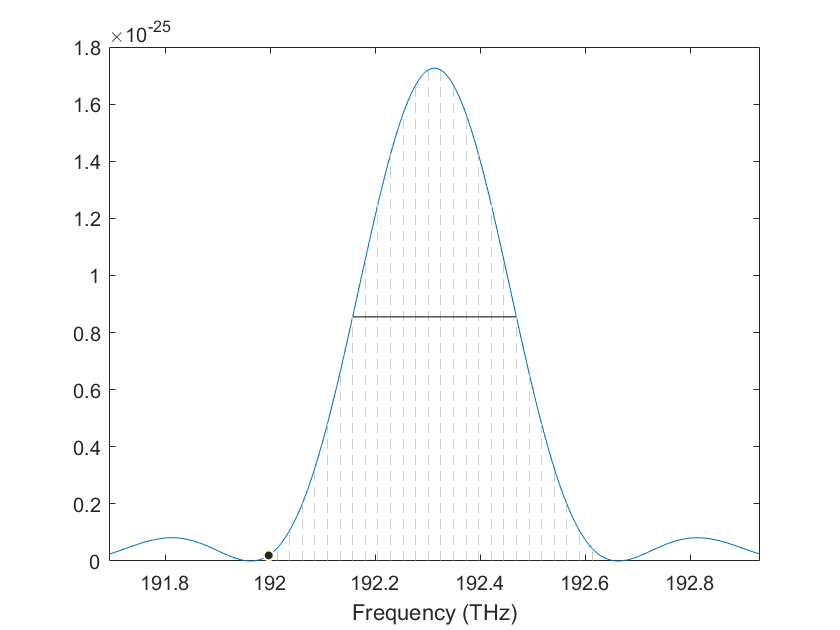

scale = 1e12; % plot axis in THz
chan_freqs = unique([lo_freq_bounds(:); hi_freq_bounds(:)]); % spectral slice boundary frequencies

% generate plot domain and add frequency points of interest
spect_freqs = linspace(0.9*min(lo_freq_bounds,[],'all'), 1.1*max(hi_freq_bounds, [], 'all'), 10000);
spect_freqs = unique([spect_freqs wss_f0_hz lo_freq_bounds(:)' hi_freq_bounds(:)']);

% Evaluate spectrum
full_spect = power_spect(spect_freqs);

% Plotting spectrum
spect_fig = figure();
plot(spect_freqs./scale, full_spect)
xlim([wss_f0_hz-2*spect_fwhm_hz, wss_f0_hz + 2*spect_fwhm_hz]/scale)

hold on

% Plotting spectral slice boundaries
stem(chan_freqs./scale, power_spect(chan_freqs), 'Color', [0.8 0.8 0.8], 'LineStyle', '--', 'MarkerSize', 0.0001)

% Plotting FWHM line
half_max = max(full_spect)/2;
fwhm_inds = find(abs(full_spect - half_max) < eps(half_max)*1e14);
fwhm_freqs_hz = [wss_f0_hz-spect_fwhm_hz/2 wss_f0_hz+spect_fwhm_hz/2];
plot(fwhm_freqs_hz/scale, full_spect(fwhm_inds([1,end])), 'k-')
xlabel("Frequency (THz)")

## Plot Channel Flux Plot

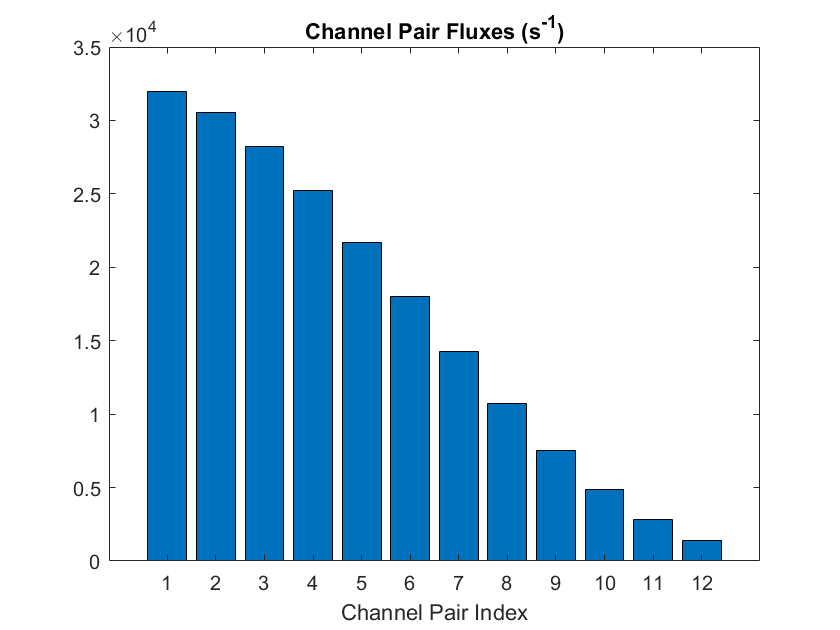

chan_flux_fig = figure();
bar(chan_flux)
title("Channel Pair Fluxes (s^{-1})")
xlabel("Channel Pair Index")

## Plot Link Fluxes

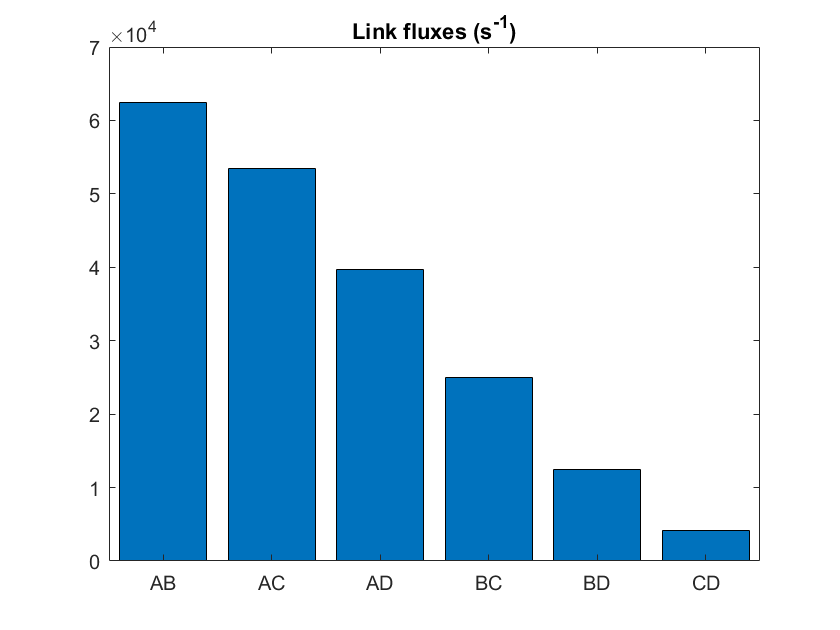

link_flux_fig = figure();
bar(categorical(link_names), link_fluxes(2:end))
title("Link fluxes (s^{-1})")

## Plot User fluxes

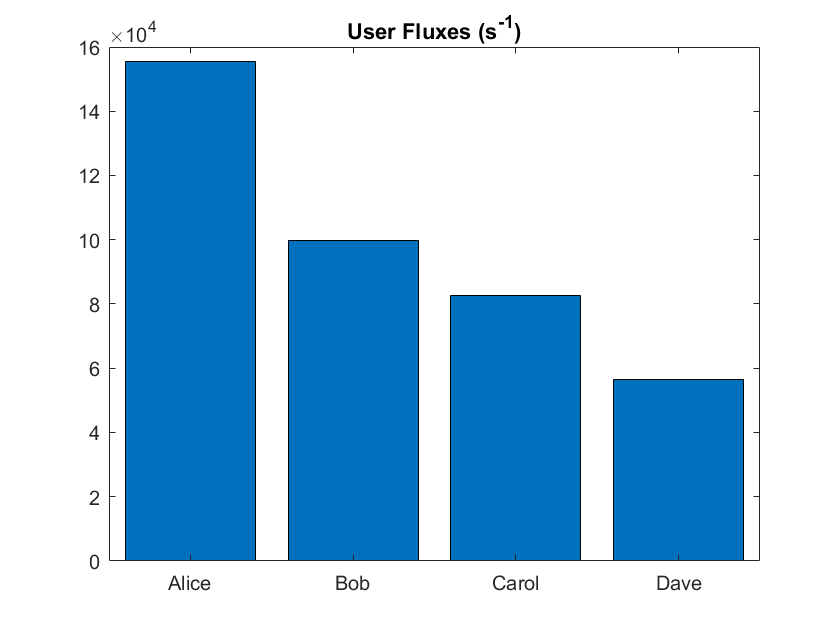

user_flux_fig = figure();
bar(categorical(user_names), user_fluxes)
title("User Fluxes (s^{-1})")

## Plot User singles count rates

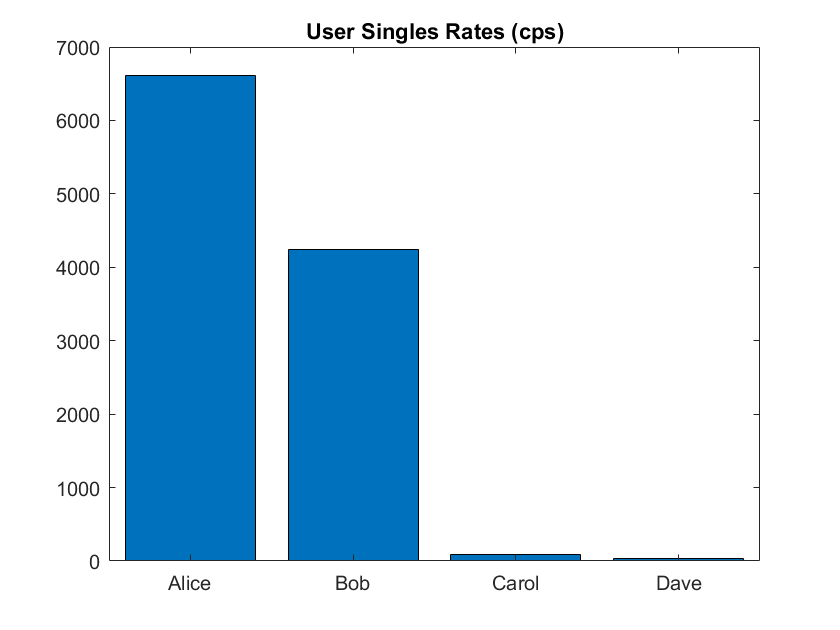

user_RN_fig = figure();
bar(categorical(user_names), R_N)
title("User Singles Rates (cps)")

## Plot Link Coincidence rates

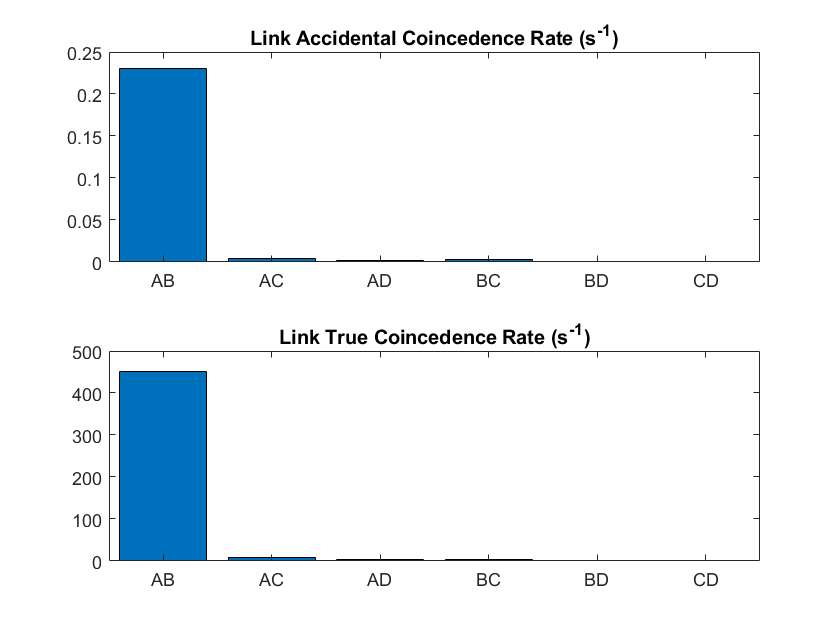

link_coinc_fig = figure();
subplot(2,1,1)
bar(categorical(link_names),A_L)
title("Link Accidental Coincedence Rate (s^{-1})")
subplot(2,1,2)
bar(categorical(link_names),C_L)
title("Link True Coincedence Rate (s^{-1})")